# **Loads Processing**

**Demonstrates how to easily create loads.**

clc; clear;

opsMAT = OpenSeesMatlab();
ops = opsMAT.opensees;

ops.wipe();
ops.model("basic", "-ndm", 3, "-ndf", 6);
ops.node(1, 0, 0, 1);
ops.node(2, 0, 2, 1);
ops.node(3, 2, 2, 1);
ops.node(4, 2, 0, 1);

ops.geomTransf("Linear", 1, 0, 0, 1);
ops.element("elasticBeamColumn", 1, 1, 2, 1000, 1000, 1000, 1000, 1000, 1000, 1);
ops.element("elasticBeamColumn", 2, 2, 3, 1000, 1000, 1000, 1000, 1000, 1000, 1);
ops.element("elasticBeamColumn", 3, 3, 4, 1000, 1000, 1000, 1000, 1000, 1000, 1);
ops.element("elasticBeamColumn", 4, 4, 1, 1000, 1000, 1000, 1000, 1000, 1000, 1);
ops.element("elasticBeamColumn", 5, 1, 3, 1000, 1000, 1000, 1000, 1000, 1000, 1);

ops.timeSeries("Linear", 1);
ops.pattern("Plain", 1, 1);
opsMAT.pre.beamGlobalUniformLoad([1, 2, 3, 4, 5], wy=2, wz=-2);

ops.pattern("Plain", 2, 1);
opsMAT.pre.beamGlobalPointLoad([1, 2, 3, 4, 5], py=2, pz=-3, xl=0.5);
a= opsMAT.post.getModelData();

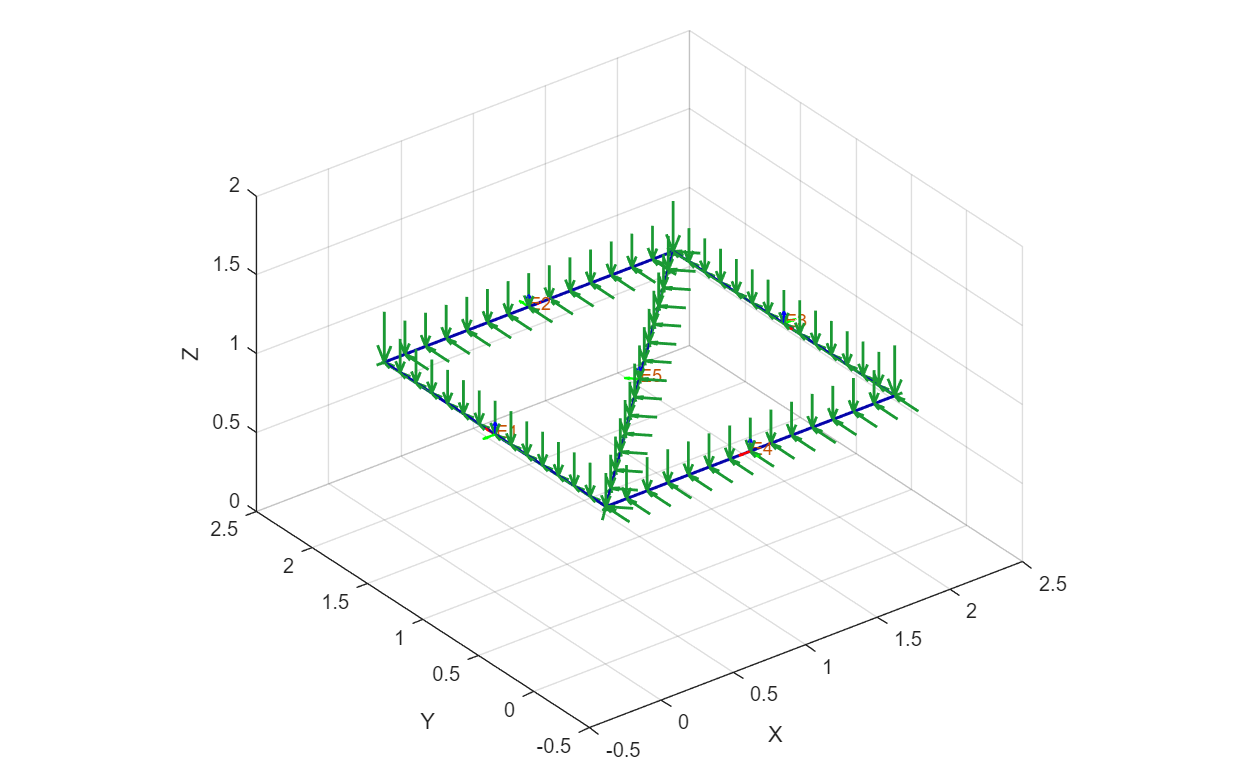

figure;
opts = opsMAT.vis.defaultPlotModelOptions;
opts.loads.showNodal = true;
opts.loads.showElement = true;
opts.loads.scale = 2;
opts.localAxes.showBeam = true;
opts.elements.showLabels = true;

opsMAT.vis.plotModel(opts=opts);
zlim([0,2]);